close all
clear all
clc

%% Import dati
opts=detectImportOptions('./data/MiniProjectEFSA.xlsx');
warning('OFF', 'MATLAB:table:ModifiedAndSavedVarnames')
data=readtable('./data/MiniProjectEFSA.xlsx', opts);
data.Properties.VariableNames={'response','numberOfAnimals','SD','dose','sex','endpoint'};

weights= 1./(data.SD.^2);
gender_female = categorical(data.sex);
endpoint = categorical(data.endpoint);

temp_endpoint=dummyvar(endpoint);
endpoint_1=logical(temp_endpoint(:,1));
endpoint_2=logical(temp_endpoint(:,2));

tbl=table(data.response,data.numberOfAnimals,data.dose,gender_female,endpoint_1,endpoint_2);
tbl.Properties.VariableNames={'response','nOa','dose','female','endpoint_1','endpoint_2'};

mdl = stepwiselm(tbl,'ResponseVar','response','Weights',weights)

1. Adding endpoint_2, FStat = 50.124, pValue = 4.21647e-07
2. Adding endpoint_1, FStat = 184.0545, pValue = 7.339523e-12
3. Adding dose, FStat = 5.6765, pValue = 0.02723


mdl = Linear regression model:
    response ~ 1 + dose + endpoint_1 + endpoint_2

Estimated Coefficients:
                    Estimate        SE         tStat       pValue  
                    _________    _________    _______    __________

    (Intercept)        18.855      0.46824     40.267    1.2778e-20
    dose            -0.013944    0.0058524    -2.3825       0.02723
    endpoint_1_1       336.75        22.43     15.013    2.3673e-12
    endpoint_2_1       25.616       1.0638     24.079    3.0394e-16


Number of observations: 24, Error degrees of freedom: 20
Root Mean Squared Error: 1.82
R-squared: 0.976,  Adjusted R-Squared: 0.972
F-statistic vs. constant model: 267, p-value = 2.66e-16

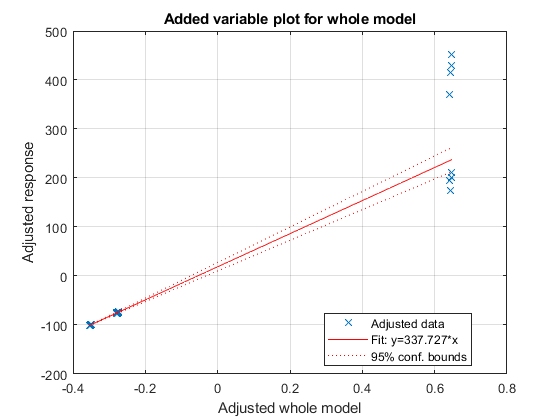

plot(mdl)
grid on

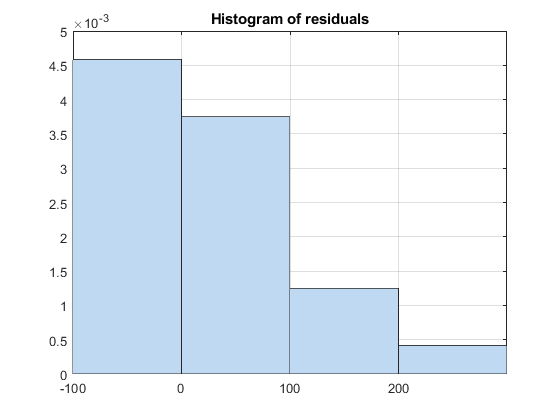

plotResiduals(mdl)
grid on

anova(mdl)

ans = 4×5 table
                  SumSq     DF    MeanSq      F         pValue  
                  ______    __    ______    ______    __________

    dose          18.825     1    18.825    5.6765       0.02723
    endpoint_1    747.49     1    747.49     225.4    2.3673e-12
    endpoint_2    1922.8     1    1922.8    579.82    3.0394e-16
    Error         66.325    20    3.3162                        


coefCI(mdl)

ans =    17.8779   19.8314
   -0.0262   -0.0017
  289.9654  383.5427
   23.3966   27.8347
